# `Problem 1: Lead Compensator for Speed Improvement`

### Baseline PID Performance:

- Design a PID controller to achieve zero steady-state error 

- Use MATLAB’s PID Tuner or manual tuning 

s = tf('s');
G = 20 / (s*(s+2)*(s+5)); % Defining transfer function
C = pidtune(G, 'PID'); % Automatic Tuner
T = feedback(C * G, 1); % Closed-Loop system


- Plot the step response and record: 

- Rise time 

- Settling time (2% criterion) 

- Overshoot percentage

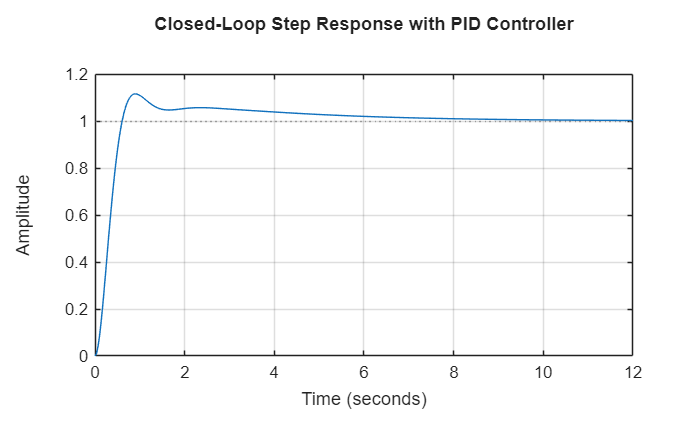

step(T)
grid on
title('Closed-Loop Step Response with PID Controller')

info = stepinfo(T);
fprintf('Rise Time: %.3f s\n', info.RiseTime)

Rise Time: 0.408 s


fprintf('Settling Time: %.3f s\n', info.SettlingTime)

Settling Time: 5.951 s


fprintf('Overshoot: %.2f %%', info.Overshoot)

Overshoot: 11.54 %

### Lead Compensator Design:

- Design a Lead Compensator with the form: C_lead(s) = K_c * (s + z) / (s + p) where |z| < |p| 

- Try: z = 3, p = 15, and tune K_c for good response 

- Combine with your PID: C_total(s) = C_PID(s) × C_lead(s) 

K_c = 15; % Tuned-value
C_lead = tf( K_c * [1 3], [1 15]); % Lead Compensator
C_total = C * C_lead; % Combining PID

- Plot the step response

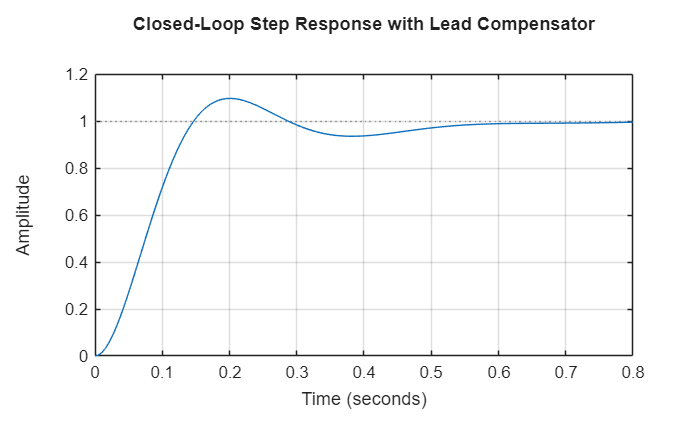

T_lead = feedback(C_total * G, 1); % Closed-loop system
step(T_lead)
grid on
title('Closed-Loop Step Response with Lead Compensator')

info_lead = stepinfo(T_lead);
fprintf('Rise Time: %.3f s\n', info_lead.RiseTime)

Rise Time: 0.098 s


fprintf('Settling Time: %.3f s\n', info_lead.SettlingTime)

Settling Time: 0.535 s


fprintf('Overshoot: %.2f %%\n', info_lead.Overshoot)

Overshoot: 9.61 %


### Performance Comparison:

- Create a comparison plot showing: 

- PID only response 

- PID + Lead Compensator response 

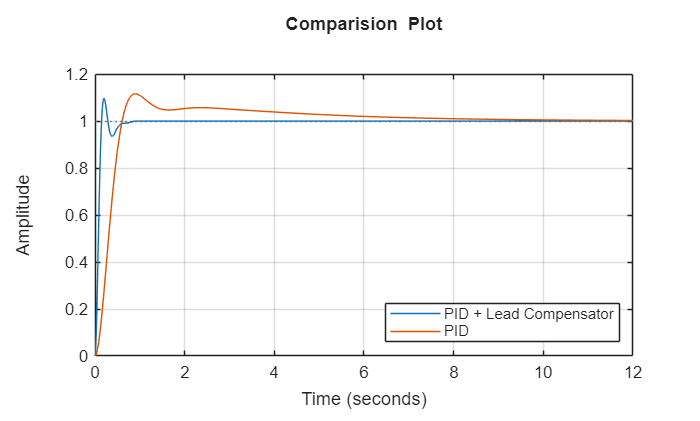

step(T_lead, T)
grid on
title('Comparision  Plot')
legend('PID + Lead Compensator', 'PID', 'Location', 'southeast')

- Create a table comparing metrics: 

- Rise time improvement 

- Settling time improvement 

- Effect on overshoot 

ControllerType = {'PID'; 'PID + Lead Compensator'};
RiseTime = [info.RiseTime; info_lead.RiseTime];
SettlingTime = [info.SettlingTime; info_lead.SettlingTime];
Overshoot = [info.Overshoot; info_lead.Overshoot];

PerformanceTable = table(RiseTime, SettlingTime, Overshoot, ...
    'RowNames', ControllerType);

disp(PerformanceTable)

                              RiseTime    SettlingTime    Overshoot
                              ________    ____________    _________

    PID                        0.40833       5.9509        11.538  
    PID + Lead Compensator    0.098212      0.53455        9.6126  



- Explain how the lead Compensator improved the transient response

*Reduces rise time due to faster system response, reduces settling time because oscillations decay more quickly, lowers overshoot due to improved damping.*

### Parameter Experimentation:

- Try different zero-pole combinations: 

-  z = 2, p = 10 

-  z = 5, p = 20 

-  z = 4, p = 12 

C1_lead = tf( K_c * [1 2], [1 10]); % Lead Compensator
C1_total = C * C1_lead; % Combining PID
T1_lead = feedback(C1_total * G, 1); % Closed-loop system

C2_lead = tf( K_c * [1 5], [1 20]); % Lead Compensator
C2_total = C * C2_lead; % Combining PID
T2_lead = feedback(C2_total * G, 1); % Closed-loop system

C3_lead = tf( K_c * [1 4], [1 12]); % Lead Compensator
C3_total = C * C3_lead; % Combining PID
T3_lead = feedback(C3_total * G, 1); % Closed-loop system

- Plot all responses on one figure

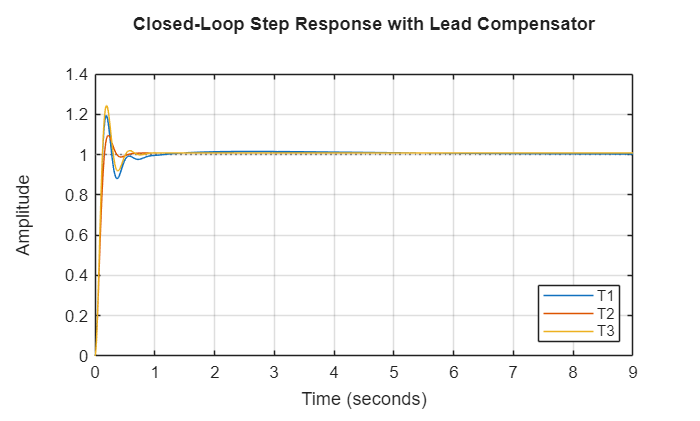

step(T1_lead, T2_lead, T3_lead)
grid on
title('Closed-Loop Step Response with Lead Compensator')
legend('T1', 'T2', 'T3', 'Location', 'southeast')

- Discuss how the zero-pole placement affects the speed of response

*Smaller pole–zero separation implies modest speed improvement (smoother response). Larger separation means more phase lead, faster rise time (but risk of overshoot). Zeros closer to the origin improve response speed earlier. Poles further left reduce high-frequency amplification and noise sensitivity*

# `Problem 2: Lag Compensator for Steady-State Accuracy`

### Proportional Controller Analysis:

- Implement a P controller with Kp = 2 

- Apply a unit step reference 

s = tf('s');
G = 50 / ((s+1)*(s+3)*(s+8)); % Define Transfer-function

K_p = 2;
C = K_p; % P Controller
T = feedback(C * G, 1);

- Measure and report the steady-state error

% Steady-state error
ess = 1 - dcgain(T);
fprintf('Steady-State Error : %.4f \n', ess)

Steady-State Error : 0.1935 


- Plot the response showing the error clearly

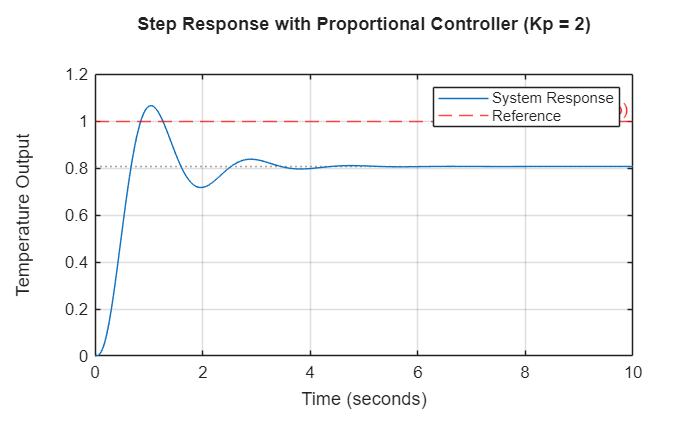

figure;
step(T, 10)
grid on
title('Step Response with Proportional Controller (Kp = 2)')
xlabel('Time')
ylabel('Temperature Output')

% Reference line
hold on
yline(1, '--r', 'Reference (Unit Step)')
legend('System Response', 'Reference')

### Lag Compensator Design:

- Design a lag Compensator: C_lag(s) = K_c * (s + z) / (s + p) , where |z| > |p| 

- Try: z = 1, p = 0.1, K_c = 1

- Combine with P controller: C(s) = K_p × C_lag(s)

% Lag-Compensator Parameters
z = 1;
p = 0.1;
K_c = 1;
K_p = 2;

s = tf('s');
G = 50 / ((s+1)*(s+3)*(s+8)); % Define Transfer-function

% Lag-Compensator and Controller
C_lag = K_c * (s + z) / (s + p);
C = K_p * C_lag;

T_lag = feedback(C * G, 1); % Closed-loop system with lag Compensator

- Plot the step response

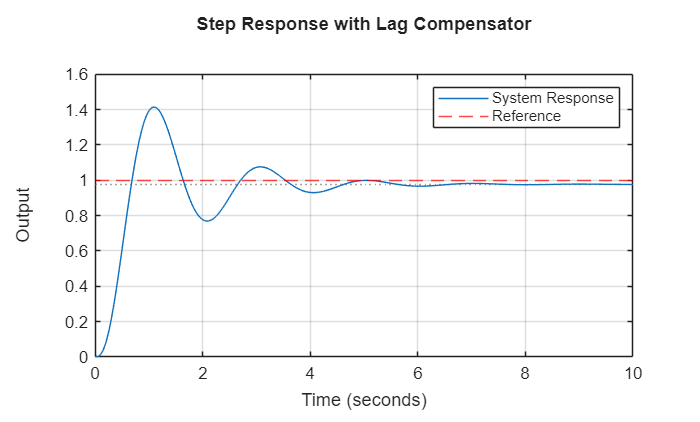

% Plot the step response
figure;
step(T_lag, 10)
grid on
title('Step Response with Lag Compensator')
xlabel('Time')
ylabel('Output')

% Reference line (unit step)
hold on
yline(1, '--r')
legend('System Response', 'Reference')

### Steady-State Error Reduction:

- Compare steady-state errors:

- P controller only

- P + Lag Compensator

% Steady-State Error for P + Lag Compensator
ess_lag = 1 - dcgain(T_lag);
fprintf('Steady-State Error with Lag Compensator: %.4f \n', ess_lag)

Steady-State Error with Lag Compensator: 0.0234 


fprintf('Steady-State Error without Lag Compensator: %.4f \n', ess)

Steady-State Error without Lag Compensator: 0.1935 


- Create a table showing:

- Steady-state error (calculate as: ess = |r_final − y_final|)

- Error reduction percentage

- Settling time for both cases

% Error Reduction Percentage
error_reduction = ((ess - ess_lag) / ess) * 100;

% Creating Table
Controller = {'P Only'; 'P + Lag'};
SteadyStateError = [ess; ess_lag];
ErrorReductionPercent = [0; error_reduction];
SettlingTime = [stepinfo(T).SettlingTime; stepinfo(T_lag).SettlingTime];

ResultsTable = table( ...
    SteadyStateError, ...
    ErrorReductionPercent, ...
    SettlingTime, ...
    'RowNames', Controller);
disp(ResultsTable)

               SteadyStateError    ErrorReductionPercent    SettlingTime
               ________________    _____________________    ____________

    P Only          0.19355                    0               3.2198   
    P + Lag        0.023438               87.891               5.2126   



- Explain why the Lag Compensator reduces steady-state error

*A Lag Compensator reduces steady-state error because it increases the system’s low-frequency gain without significantly affecting high-frequency dynamics.*

### Trade-off Analysis:

- Observe and document any negative effects of the lag compensator:

`Does settling time increase?`

*Yes, reducing the pole value increased the Settling-Time.*

`Is the response slower?`

*As the pole moves closer to the origin. The system responds more slowly and the Rise time increases. Therefore, stronger lag compensation slows the transient response.*

- Try reducing the pole value to p = 0.01 and compare

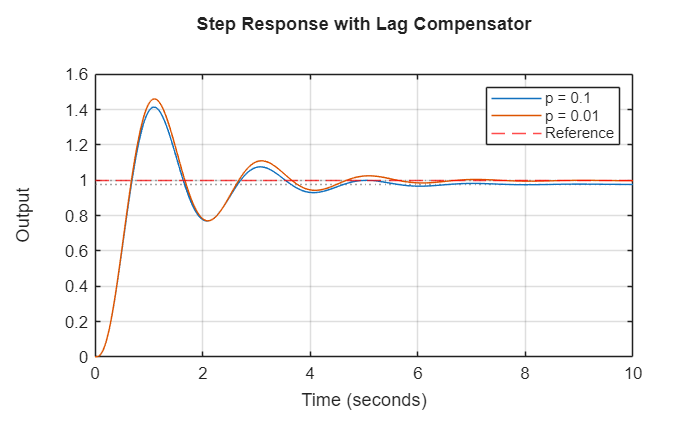

% Lag-Compensator Parameters
z = 1;
p = 0.01;
K_c = 1;
K_p = 2;

s = tf('s');
G = 50 / ((s+1)*(s+3)*(s+8)); % Define Transfer-function

% Lag-Compensator and Controller
C1_lag = K_c * (s + z) / (s + p);
C1 = K_p * C1_lag;

T1_lag = feedback(C1 * G, 1); % Closed-loop system with lag Compensator

% Plot the step response
figure;
step(T_lag, T1_lag, 10)
grid on
title('Step Response with Lag Compensator')
xlabel('Time')
ylabel('Output')

% Reference line (unit step)
hold on
yline(1, '--r')
legend('p = 0.1', 'p = 0.01', 'Reference')

*Significantly reduction in steady-state error and increase in low-frequency gain is observed by reducing p from 0.1 to 0.01*

- Discuss the trade-off between accuracy and speed

*As the lag compensator pole moves closer to zero (e.g., p = 0.01), the low-frequency gain increases. The system output gets closer to the reference, improving long-term accuracy. Increasing low-frequency gain also introduces slower dynamics, because the compensator’s pole is near the origin. The system takes longer to reach steady state, making the response sluggish.*

# `Problem 3: Feedforward + Feedback Control`

### Feedback-Only Control:

- Design a PI controller: C_fb(s) = K_p + K_i / s , with K_p = 2, K_i = 1

- Create a disturbance signal: d(t) = 0.3 · step(t − 5) (uphill starts at t = 5 s)

- Simulate using lsim() with:

-     Reference speed: r(t) = 1 (constant)

-     Disturbance injected at plant output: y = G(u) − d

% Time Vector
t = 0:0.01:30;

% Plant
G = tf(1, [1 0.5]);
C = tf([2 1], [1 0]);

% Closed-loop transfer functions
Tr = feedback(C*G,1);
Td = feedback(1,C*G);

% Reference response
[y_r,~] = step(Tr,t);

% Disturbance
d = 0.3*(t >= 5);
y_d = lsim(Td,d,t);

% Total output
y = y_r - y_d;

% Error
e = 1 - y;

- Plot: reference, output, and error over time

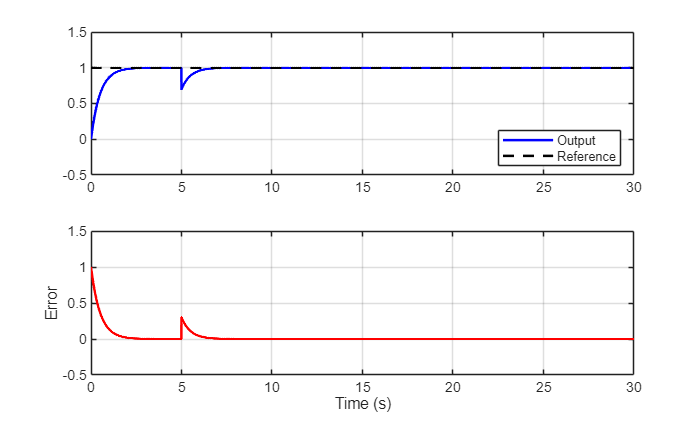

figure;
subplot(2,1,1)
plot(t,y,'b',t,ones(size(t)),'k--','LineWidth',1.5)
legend('Output','Reference', 'Location', 'southeast')
grid on
ylim([-0.5 1.5])

subplot(2,1,2)
plot(t,e,'r','LineWidth',1.5)
xlabel('Time (s)')
ylabel('Error')
grid on
ylim([-0.5 1.5])

- Measure: maximum error and recovery time when disturbance hits

max_error = max(abs(e(t >= 5)));
fprintf('Max Error: %.4f\n', max_error)

Max Error: 0.3000



tol = 0.02;     % 2% tolerance
recovery_time = NaN;

for k = 1:length(t)
    if t(k) >= 5 && abs(e(k)) <= tol
        recovery_time = t(k) - 5;
        break
    end
end

fprintf('Recovery Time : %.2f s\n', recovery_time)

Recovery Time : 1.36 s


### Adding Feedforward Control:

- Design a feedforward controller that predicts the disturbance

- Feedforward gain: K_ff = 1 / dcgain(G) (inverse of plant DC gain)

- Total control signal: u = u_feedback + K_ff · d_predicted

- Simulate with the same disturbance

% Feedforward gain
Kff = 1 / dcgain(G);

% Predicted disturbance (assumed perfectly known)
d_pred = d;

% Disturbance path WITH feedforward compensation
y_d_ff = lsim(G, d - Kff*d_pred, t);

% Total output with feedforward
y_ff = y_r - y_d_ff;

% Error with feedforward
e_ff = 1 - y_ff;

- Plot: reference, output, and error

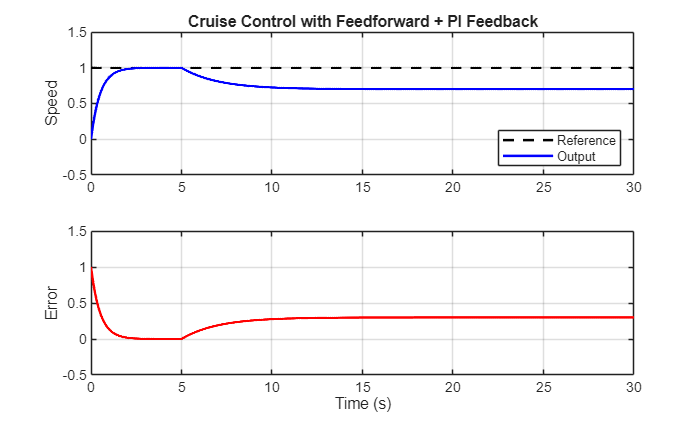

figure;
subplot(2,1,1)
plot(t, ones(size(t)),'k--','LineWidth',1.5); hold on;
plot(t, y_ff,'b','LineWidth',1.5)
legend('Reference','Output','Location','southeast')
ylabel('Speed')
grid on
ylim([-0.5 1.5])
title('Cruise Control with Feedforward + PI Feedback')

subplot(2,1,2)
plot(t, e_ff,'r','LineWidth',1.5)
xlabel('Time (s)')
ylabel('Error')
grid on
ylim([-0.5 1.5])

% Maximum error after disturbance
max_error_ff = max(abs(e_ff(t >= 5)));
fprintf('Max Error with Feedforward: %.4f\n', max_error_ff)

Max Error with Feedforward: 0.3000


fprintf('Final Error with Feedforward: %.4f\n', e_ff(end))

Final Error with Feedforward: 0.3000


###  Performance Comparison:

- Create comparison plots:

-     Output response (feedback only vs feedforward+feedback)

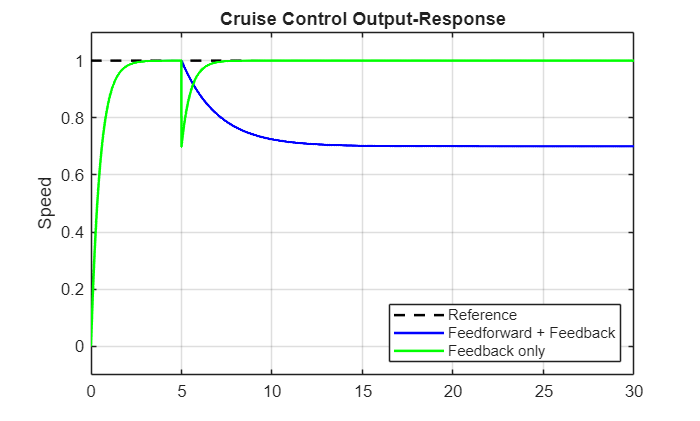

figure;
plot(t, ones(size(t)),'k--','LineWidth',1.5); hold on;
plot(t, y_ff,'b','LineWidth',1.5)
plot(t, y,'g','LineWidth',1.5)
legend('Reference','Feedforward + Feedback','Feedback only', ...
    'Location','southeast')
ylabel('Speed')
grid on
ylim([-0.1 1.1])
title('Cruise Control Output-Response')

-     Error signals for both cases

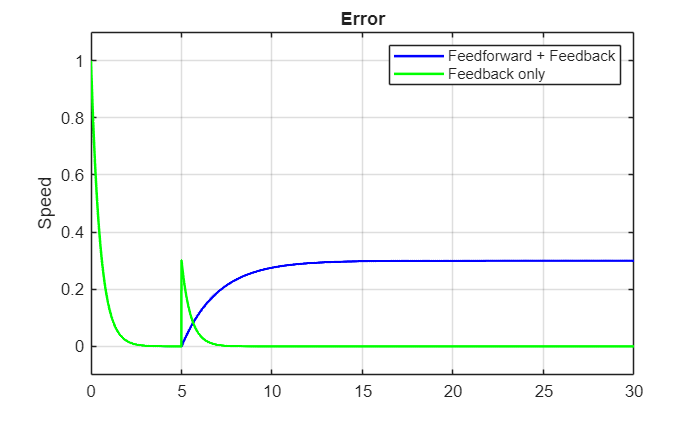

figure;
plot(t, e_ff,'b','LineWidth',1.5)
hold on;
plot(t, e,'g','LineWidth',1.5)
legend('Feedforward + Feedback','Feedback only')
ylabel('Speed')
grid on
ylim([-0.1 1.1])
title('Error')

- Create a table comparing:

-     Maximum error when disturbance hits

-     Recovery time

-     Steady-state error after disturbance

% Creating Table
Controller = {'Feedback Only'; 'Feedback + Feedforward'};
MaximumError = [max_error; max_error_ff];
RecoveryTime = [recovery_time; NaN];
% Since, Feedback + Feedforward does not recover
% Calculating its Recovery Time makes no sense
SteadyStateError = [e(end); e_ff(end)];

ResultsTable = table( ...
    MaximumError, ...
    RecoveryTime, ...
    SteadyStateError, ...
    'RowNames', Controller);
disp(ResultsTable)

                              MaximumError    RecoveryTime    SteadyStateError
                              ____________    ____________    ________________

    Feedback Only               0.30005           1.36           1.5543e-15   
    Feedback + Feedforward          0.3            NaN                  0.3   



- Explain why feedforward helps with disturbance rejection

*Feedforward helps with disturbance rejection because it acts before the disturbance creates an error, whereas feedback can only react after the error has already appeared.*

### Unpredicted Disturbance Test:

- Add an unpredicted disturbance at t = 15 s : d_unpredicted(t) = 0.2 · step(t − 15) 

- Keep feedforward compensating only the first disturbance

- Show that feedback control handles the unpredicted disturbance

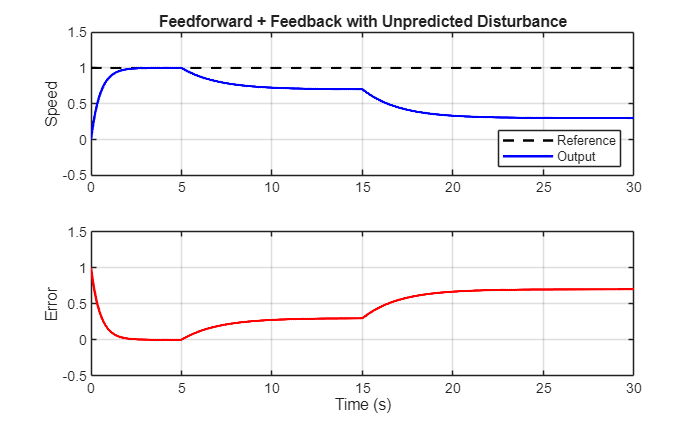

% Unpredicted disturbance
d1 = 0.2*(t >= 15);

% Total disturbance
d_total = d + d1;

% Feedforward compensates ONLY predicted disturbance
d_pred = d;

% Output disturbance effect with feedforward
y_d_ff = lsim(G, d_total - Kff*d_pred, t);

% Total output
y_ff_unpred = y_r - y_d_ff;

% Error
e_ff_unpred = 1 - y_ff_unpred;

figure;
subplot(2,1,1)
plot(t, ones(size(t)),'k--','LineWidth',1.5); hold on;
plot(t, y_ff_unpred,'b','LineWidth',1.5)
ylabel('Speed')
legend('Reference','Output','Location','southeast')
grid on
ylim([-0.5 1.5])
title('Feedforward + Feedback with Unpredicted Disturbance')

subplot(2,1,2)
plot(t, e_ff_unpred,'r','LineWidth',1.5)
xlabel('Time (s)')
ylabel('Error')
grid on
ylim([-0.5 1.5])

- Discuss the complementary nature of feedforward and feedback

*Feedforward control improves performance by reducing the effect of predictable disturbances, such as an uphill road, before they affect the system output. Feedback control, on the other hand, is necessary to correct for unpredicted disturbances and modeling errors. When both are used together, the system achieves faster disturbance rejection while maintaining robustness and accuracy.*

# `Problem 4: Simple MIMO System Control`

### Open-Loop MIMO Analysis:

- Create the MIMO transfer function in MATLAB

- Apply step inputs: u_1 = 1, u_2 = 0

% Creating MIMO transfer function
G11 = tf (2 , [1 1]) ; % Effect of u1 on h1
G12 = tf (0.5 , [1 2]) ; % Effect of u2 on h1 ( coupling !)
G21 = tf (1 , [1 1.5]) ; % Effect of u1 on h2 ( coupling !)
G22 = tf (3 , [1 1]) ; % Effect of u2 on h2

% Creating MIMO system as a matrix
G = [ G11 G12 ; G21 G22 ]; % 2 x 2 MIMO system

% Using lsim () for MIMO
t = 0:0.01:20;
u1 = ones(size(t)); % Step input to u1
u2 = zeros(size(t)); % No input to u2
u = [u1 ; u2]'; % Combine inputs ( note the transpose !)

[y , t] = lsim (G , u , t ) ;
% y(:,1) is h1 (tank 1 level)
% y(:,2) is h2 (tank 2 level)

- Plot both outputs h1 and h2 to see the coupling effect

plot(t , y(:,1), 'b', t, y(:,2), 'r', 'LineWidth', 1.5);
grid on
legend ('h1 (Tank 1)', 'h2 (Tank 2)');
ylim([0 2.1])
xlabel('Time (seconds)')
ylabel('Output')
title('Response for u1 = 1, u2 = 0')

- Repeat with: u1 = 0, u2 = 1

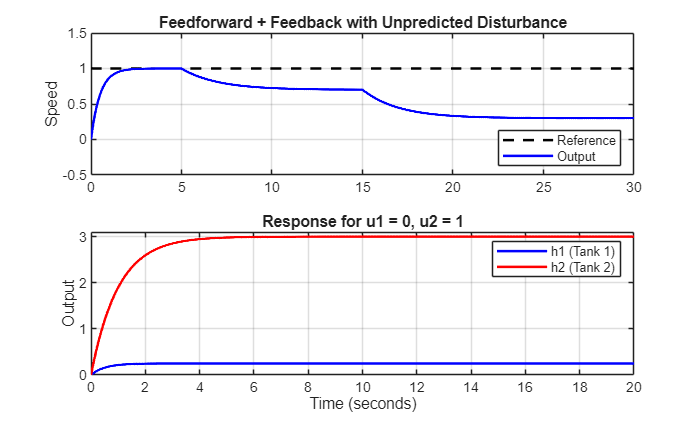

t = 0:0.01:20;
u1 = zeros(size(t)); % Step input to u1
u2 = ones(size(t)); % No input to u2
u = [u1 ; u2]'; % Combine inputs ( note the transpose !)

[y, t] = lsim(G, u, t);
% y(:,1) is h1 (tank 1 level)
% y(:,2) is h2 (tank 2 level)

plot(t , y(:,1), 'b', t, y(:,2), 'r', 'LineWidth', 1.5);
grid on
legend ('h1 (Tank 1)', 'h2 (Tank 2)');
ylim([0 3.1])
xlabel('Time (seconds)')
ylabel('Output')
title('Response for u1 = 0, u2 = 1')

- Explain how changing one input affects both outputs

*Changing one input affects both outputs because each output is the sum of a direct path and a cross-coupling path, making the MIMO system coupled rather than independent.*

### Decentralized PI Control:

- Design two independent PI controllers:

- C1 controls h1 using u1 (ignoring h2)

- C2 controls h2 using u2 (ignoring h1)

- Try: Kp1 = 1.5 , Ki1 = 0.8 and Kp2 = 1.2 , Ki2 = 0.6

- Set references: r1 = 1.0 , r2 = 1.5

- Simulate the closed-loop MIMO system

% Define Laplace variable
s = tf('s');

% PI controllers
C1 = 1.5 + 0.8/s;   % Controller for h1-u1 loop
C2 = 1.2 + 0.6/s;   % Controller for h2-u2 loop

% Controller matrix (decentralized)
C = [C1  0;
     0   C2];

% Identity matrix
I = eye(2);

% Closed-loop MIMO system
T = feedback(G*C, I);   % Equivalent to (GC)/(I+GC)

% Time vector
t = 0:0.01:20;

% References
r1 = 1.0 * ones(size(t));
r2 = 1.5 * ones(size(t));
r = [r1; r2]';

% Simulate tank levels
[y, t] = lsim(T, r, t);

- Plot both tank levels and control signals

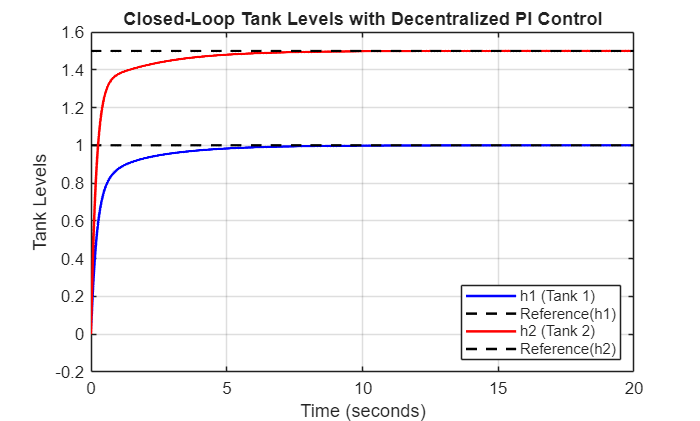

% Plot tank levels
figure;
plot(t, y(:,1), 'b', t, ones(size(t)),'k--','LineWidth', 1.5); hold on;
plot(t, y(:,2), 'r', t, 1.5*ones(size(t)),'k--','LineWidth', 1.5);
grid on;
xlabel('Time (seconds)');
ylabel('Tank Levels');
legend('h1 (Tank 1)', 'Reference(h1)','h2 (Tank 2)', ...
    'Reference(h2)','Location','southeast');
title('Closed-Loop Tank Levels with Decentralized PI Control');

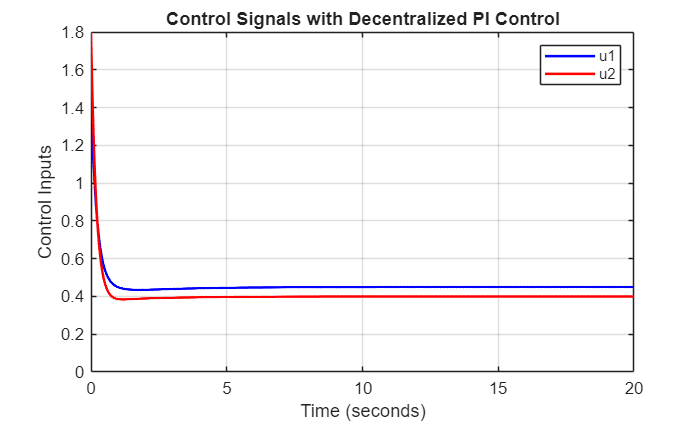

% Compute control error
e = r - y;

% Control signals
[u, ~] = lsim(C, e, t);

% Plot control inputs
figure;
plot(t, u(:,1), 'b', 'LineWidth', 1.5); hold on;
plot(t, u(:,2), 'r', 'LineWidth', 1.5);
grid on;
xlabel('Time (seconds)');
ylabel('Control Inputs');
legend('u1', 'u2');
title('Control Signals with Decentralized PI Control');
ylim([0 1.8])

### Analyzing Interaction Effects:

- Observe the coupling effects in the response:

`Does controlling h1 affect h2?`

*Yes, clearly. When the controller C1 acts to bring h1 to its reference r1 , the manipulated variable u1 also passes through the coupling path G21. This causes an unintended change in h2 even though h2 is supposed to be controlled only by u2. So, controlling h1 disturbs h2.*

`Do the outputs interfere with each other?`

*Yes. Because the plant is coupled, a correction made to one output disturbs the other. Each controller reacts not only to its own error but also to disturbances created by the other control loop, leading to interaction between h1 and h2*

`Is there overshoot or oscillation due to interaction?`

*Not significant here. But Yes, the interaction between the two control loops can produce overshoot, increased settling time, and sometimes mild oscillations, as the controllers continuously counteract the effects they introduce on each other through the coupling paths.*

- Create a table showing final settling values and settling times for both outputs

% Reference values
r1 = 1.0;
r2 = 1.5;

% Extract outputs
h1 = y(:,1);
h2 = y(:,2);

% Compute settling times for each tank
info_h1 = stepinfo(h1, t, r1);
info_h2 = stepinfo(h2, t, r2);

% Create table
Results = table( ...
    [r1; r2], ...
    [h1(end); h2(end)], ...
    [info_h1.SettlingTime; info_h2.SettlingTime], ...
    'VariableNames', {'Reference', 'FinalValue', 'SettlingTime'}, ...
    'RowNames', {'h1 (Tank 1)', 'h2 (Tank 2)'});

disp(Results);

                   Reference    FinalValue    SettlingTime
                   _________    __________    ____________

    h1 (Tank 1)         1        0.99998         4.6095   
    h2 (Tank 2)       1.5            1.5         4.1076   



### Sequential Setpoint Changes:

- Test the system with time-varying references:

- r1 = 1.0 for all time

- r2 = 1.0 for t < 10 s , then r2 = 1.5 for t ≥ 10 s

% Define Laplace variable
s = tf('s');

% PI controllers
C1 = 1.5 + 0.8/s;   % Controller for h1-u1 loop
C2 = 1.2 + 0.6/s;   % Controller for h2-u2 loop

% Controller matrix (decentralized)
C = [C1  0;
     0   C2];

% Identity matrix
I = eye(2);

% Closed-loop MIMO system
T = feedback(G*C, I);   % Equivalent to (GC)/(I+GC)

% Time vector
t = 0:0.01:20;

% References
r1 = ones(size(t));
r2 = ones(size(t)); r2(t >= 10) = 1.5;
r = [r1; r2]';

% Simulate tank levels
[y, t] = lsim(T, r, t);

- Plot the response showing how changing r2 affects h1

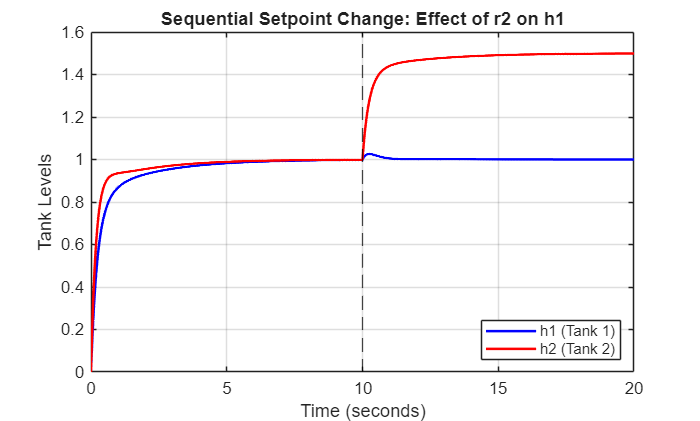

% Plot outputs
figure;
plot(t, y(:,1), 'b', 'LineWidth', 1.5); hold on;
plot(t, y(:,2), 'r', 'LineWidth', 1.5);
xline(10,'--k','LineWidth', 0.8);
grid on
xlabel('Time (seconds)')
ylabel('Tank Levels')
legend('h1 (Tank 1)', 'h2 (Tank 2)', 'Location','southeast')
title('Sequential Setpoint Change: Effect of r2 on h1')
ylim([0 1.6])

- Discuss why MIMO systems are more challenging than SISO systems

*MIMO systems are harder to control because inputs and outputs are interconnected. In this system, a control action intended for one output also affects the other output through coupling paths. As a result, controllers can no longer be designed independently, and each control loop may introduce disturbances into the others. This interaction can lead to overshoot, longer settling times, oscillations, and degraded performance. In contrast, SISO systems have a one-to-one relationship between input and output, making controller design and tuning much simpler.*

- Suggest how the controllers could be improved (conceptually, no implementation needed)

***Decoupling control***

*Add a decoupler to cancel cross-coupling terms G12 and G21 , making the system behave approximately like two independent SISO loops.*

***Centralized MIMO control***

*Design controllers that use both errors (h1, h2) to compute both inputs (u1,u2), explicitly accounting for coupling.*

***Advanced control strategies***

*Apply model predictive control or state-space methods that naturally handle multivariable interactions and constraints.*

# `Summary Questions`

After completing all problems, answer these briefly:

`When would you choose a lead compensator over increasing PID gains?`

*In particular, a lead compensator is preferred when increasing PID gains causes excessive overshoot, oscillations, or instability. Higher gains may speed up the response, but they also reduce phase margin and can excite unmodeled dynamics or noise. A lead compensator, on the other hand, adds positive phase lead around the crossover frequency, which increases phase margin and allows the system to respond faster without sacrificing stability.*

*When the system has sluggish transient response or poor rise time due to limited bandwidth, but is already close to its gain limits. In such cases, lead compensation shifts the frequency response to achieve faster dynamics while keeping gains moderate.*

`What are the main advantages and limitations of lag compensators?`

***Advantages:***

*The primary advantage of a lag compensator is its ability to reduce steady-state error without requiring a large increase in controller gain. By increasing low-frequency gain, it improves tracking of constant or slowly varying references and enhances disturbance rejection. Lag compensators are also relatively simple to design and implement, and they typically have a minimal destabilizing effect compared to aggressive gain increases.*

***Limitations:***

*The main limitation of a lag compensator is that it slows down the transient response. Because it adds phase lag near the crossover frequency, it can reduce phase margin, leading to longer rise and settling times and, in some cases, increased overshoot. Lag compensators also do not improve system speed or stability margins and are ineffective for systems that require faster dynamics. As a result, they are often combined with lead compensation when both steady-state accuracy and good transient performance are required.*

`Why is feedforward control called ”proactive” compared to feedback?`

*Feedforward control is called proactive because it takes action before a problem shows up at the output. If a disturbance or a change in input is known or measured, the controller adjusts the control signal immediately to counter it. Feedback control, on the other hand, can only act after the output has already changed and an error is detected. So feedback always reacts to something that has already happened, while feedforward tries to prevent the error from happening in the first place.*

`What makes MIMO systems more difficult to control than SISO systems?`

*MIMO systems are more difficult to control than SISO systems mainly because the inputs and outputs are interconnected. In a MIMO system, one control input usually affects more than one output, so a control action intended to correct one variable can unintentionally disturb others. This interaction makes it hard to tune controllers independently, since adjusting one loop can change the behavior of the entire system.*